# Train SAC Agent for Ball Balance Control

This example shows how to train a soft actor-critic (SAC) reinforcement learning agent to control a robot arm for a ball-balancing task.

clear;
close all;
bdclose('all');
addpath("/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/model");

## Introduction

The robot arm in this example is a Kinova Gen3 robot, which is a seven degree-of-freedom (DOF) manipulator. The arm is tasked to balance a ping pong ball at the center of a flat surface (plate) attached to the robot gripper. Only the final two joints are actuated and contribute to motion in the pitch and roll axes as shown in the following figure. The remaining joints are fixed and do not contribute to motion.

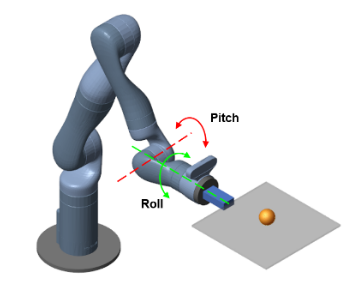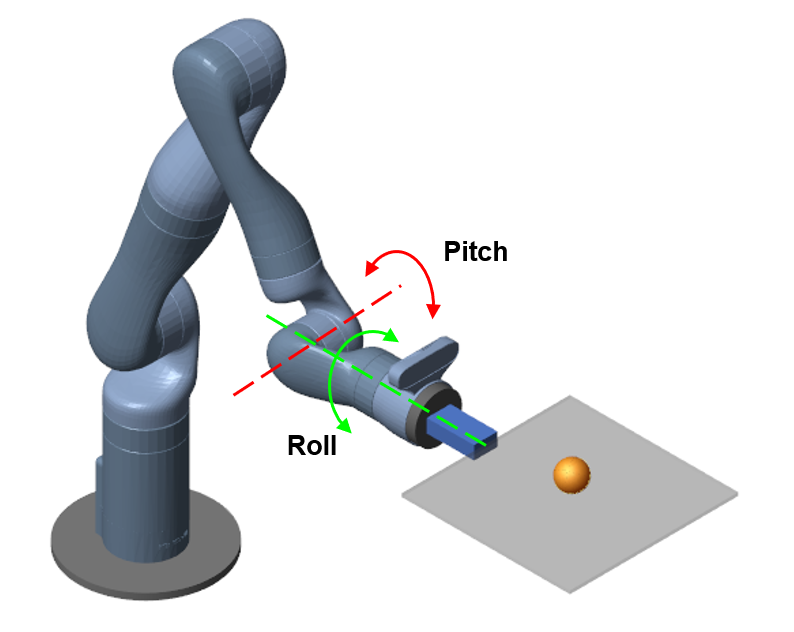

Open the Simulink® model to view the system. The model contains a Kinova Ball Balance subsystem connected to an RL Agent block. The agent applies an action to the robot subsystem and receives the resulting observation, reward, and is-done signals.

% open_system("BBC_RL_training")

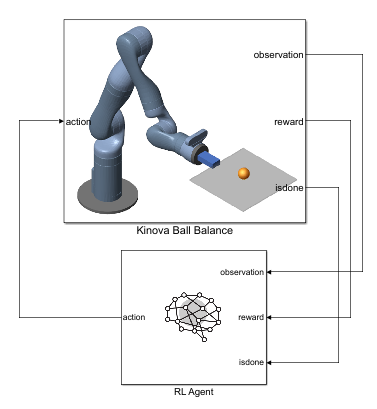

View to the Kinova Ball Balance subsystem.

% open_system("BBC_RL_training/Kinova Ball Balance")

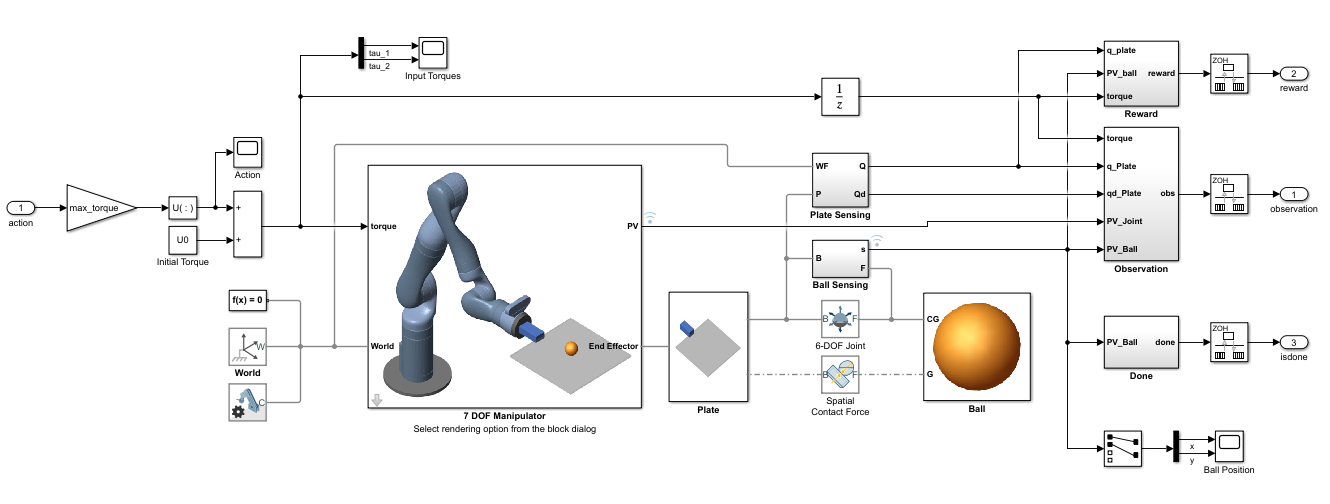

In this model:

- The physical components of the system (manipulator, ball, and plate) are modeled using Simscape™ Multibody™ components.

- The plate is constrained to the end effector of the manipulator.

- The ball has six degrees of freedom and can move freely in space.

- Contact forces between the ball and plate are modeled using the Spatial Contact Force block.

- Control inputs to the manipulator are the torque signals for the actuated joints.

Create the parameters for the example by running the `kinova_params` script included with this example. When you have the Robotics System Toolbox Robot Library Data support package installed, this script also adds the necessary mesh files to the MATLAB® path.

kinova_params;

## Define Environment

To train a reinforcement learning agent, you must define the environment with which it will interact. For the ball balancing environment:

- The observations are represented by a 22 element vector that contains information about the positions (sine and cosine of joint angles) and velocities (joint angle derivatives) of the two actuated joints, positions (x and y distances from plate center) and velocities (x and y derivatives) of the ball, orientation (quaternions) and velocities (quaternion derivatives) of the plate, joint torques from the last time step, ball radius, and mass.

- The actions are normalized joint torque values.

- The sample time is $T_s =0\ldotp 01s$, and the simulation time is $T_f =10s$.

- The simulation terminates when the ball falls off the plate.

- The reward $r_t$ at time step $t$ is given by:

                
$$\begin{array}{l}
r_t =r_{\textrm{ball}} +r_{\textrm{plate}} +r_{\textrm{action}} \\
r_{\textrm{ball}} =e^{-0\ldotp 001\left(x^2 +y^2 \right)} \\
r_{\textrm{plate}} =-0\ldotp 1\left(\phi^2 +\theta^2 +\psi^2 \right)\\
r_{\textrm{action}} =-0\ldotp 05\left(\tau_1^2 +\tau_2^2 \right)
\end{array}$$


Here, $r_{\textrm{ball}}$ is a reward for the ball moving closer to the center of the plate, $r_{\textrm{plate}}$ is a penalty for plate orientation, and $r_{\textrm{action}}$ is a penalty for control effort. $\phi$, $\theta$, and $\psi$ are the respective roll, pitch, and yaw angles of the plate in radians. $\tau_1$ and $\tau_2$ are the joint torques.

Create the observation and action specifications for the environment using continuous observation and action spaces.

numObs = 22;  % Number of observations
numAct = 2;   % Number of actions

obsInfo = rlNumericSpec([numObs 1]);

actInfo = rlNumericSpec([numAct 1]);
actInfo.LowerLimit = -1;
actInfo.UpperLimit = 1;

Create the Simulink environment interface using the observation and action specifications. For more information on creating Simulink environments, see [`rlSimulinkEnv`](docid:rl_ref#mw_12cc40dc-3191-4a23-af71-1625696c1a14).

mdl = "BBC_RL_training";
blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

Specify a reset function for the environment using the `ResetFcn` parameter. 

env.ResetFcn = @kinovaResetFcn;

This reset function (provided at the end of this example) randomly initializes the initial x and y positions of the ball with respect to the center of the plate. For more robust training, you can also randomize other parameters inside the reset function, such as the mass and radius of the ball.

Specify the sample time `Ts` and simulation time `Tf`.

Ts = 0.01;
Tf = 5;
Ts_sample = Ts;
timeTolerance = 0.5;

## Create Agent

The agent in this example is a soft actor-critic (SAC) agent. SAC agents have critics that approximate the expectation of the value function given the states and actions and an actor that models a stochastic policy. The agent selects an action based on this policy. For more information on SAC agents, see [Soft Actor-Critic Agents](docid:rl_ug#mw_66993d46-0fa5-41fa-9b73-d3caf6f9e649).

The SAC agent in this example uses two critics to learn the optimal Q-value function. Using two critics helps avoid overfitting when learning the Q-function. To create the critics, first create a deep neural network with two inputs (the observation and action) and one output. For more information on creating deep neural networks for reinforcement learning agents, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

% Set the random seed for reproducibility.
% rng(0)

% Define the network layers.
cnet = [
    featureInputLayer(numObs,"Normalization","none","Name","observation")
    fullyConnectedLayer(256,"Name","fc1")
    concatenationLayer(1,2,"Name","concat")
    reluLayer("Name","relu1")
    fullyConnectedLayer(128,"Name","fc3")
    reluLayer("Name","relu2")
    fullyConnectedLayer(64,"Name","fc4")
    reluLayer("Name","relu3")
    fullyConnectedLayer(1,"Name","CriticOutput")];
actionPath = [
    featureInputLayer(numAct,"Normalization","none","Name","action")
    fullyConnectedLayer(256,"Name","fc2")];

% Connect the layers.
criticNetwork = layerGraph(cnet);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = connectLayers(criticNetwork,"fc2","concat/in2");

View the critic neural network.

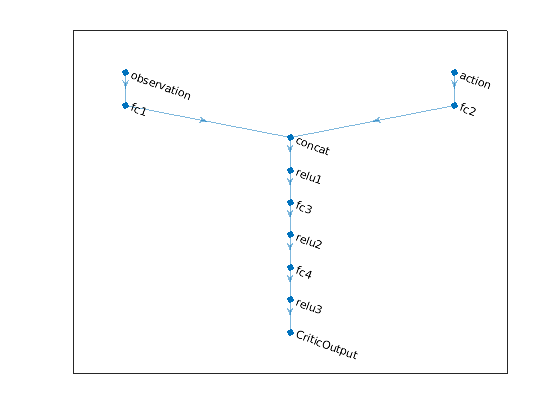

plot(criticNetwork)

When using two critics, a SAC agent requires them to have different initial parameters. Create and initialize two `dlnetwork` objects.

criticdlnet = dlnetwork(criticNetwork,'Initialize',false);
criticdlnet1 = initialize(criticdlnet);
criticdlnet2 = initialize(criticdlnet);

Create the critic functions using `rlQValueFunction`.

critic1 = rlQValueFunction(criticdlnet1,obsInfo,actInfo, ...
    "ObservationInputNames","observation");
critic2 = rlQValueFunction(criticdlnet2,obsInfo,actInfo, ...
    "ObservationInputNames","observation");

The actor function in a SAC agent is stochastic actor with a continuous action space, which you define as an `rlContinuousGaussianActor` object. Create a deep neural network to model the actor policy.

% Create the actor network layers.
anet = [
    featureInputLayer(numObs,"Normalization","none","Name","observation")
    fullyConnectedLayer(256,"Name","fc1")
    reluLayer("Name","relu1")
    fullyConnectedLayer(128,"Name","fc2")
    reluLayer("Name","relu2")];
meanPath = [
    fullyConnectedLayer(64,"Name","meanFC")
    reluLayer("Name","relu3")
    fullyConnectedLayer(numAct,"Name","mean")];
stdPath = [
    fullyConnectedLayer(numAct,"Name","stdFC")
    reluLayer("Name","relu4")
    softplusLayer("Name","std")];

% Connect the layers.
actorNetwork = layerGraph(anet);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);
actorNetwork = connectLayers(actorNetwork,"relu2","meanFC/in");
actorNetwork = connectLayers(actorNetwork,"relu2","stdFC/in");

View the actor neural network.

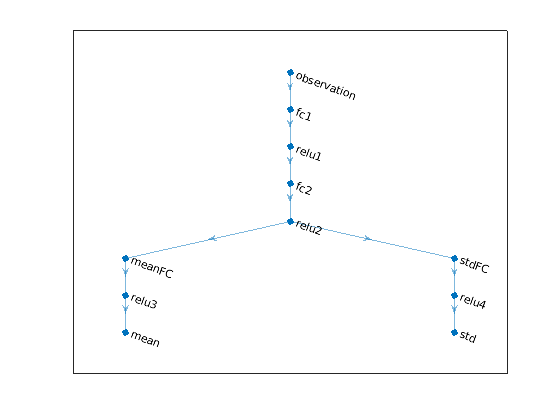

plot(actorNetwork)

Create the actor function using `rlContinuousGaussianActor`.

actordlnet = dlnetwork(actorNetwork);
actor = rlContinuousGaussianActor(actordlnet, obsInfo, actInfo, ...
    "ObservationInputNames","observation", ...
    "ActionMeanOutputNames","mean", ...
    "ActionStandardDeviationOutputNames","std");

The SAC agent in this example trains from an experience buffer of maximum capacity 1e6 by randomly selecting mini-batches of size 128. The discount factor of 0.99 is close to 1 and therefore favors long term reward with respect to a smaller value. For a full list of SAC hyperparameters and their descriptions, see [`rlSACAgentOptions`](docid:rl_ref#mw_378cf35c-0c56-448f-a836-4c236af12954).

Specify the agent hyperparameters for training. 

agentOpts = rlSACAgentOptions( ...
    "SampleTime",Ts, ...
    "TargetSmoothFactor",1e-3, ...    
    "ExperienceBufferLength",1e6, ...
    "MiniBatchSize",128, ...
    'NumStepsToLookAhead',1, ...
    "NumWarmStartSteps",1000, ...
    "DiscountFactor",0.99);

For this example the actor and critic neural networks are updated using the Adam algorithm with a learn rate of 1e-4 and gradient threshold of 1. Specify the optimizer parameters.

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 1e-4;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;

for ct = 1:2
    agentOpts.CriticOptimizerOptions(ct).Algorithm = "adam";
    agentOpts.CriticOptimizerOptions(ct).LearnRate = 1e-4;
    agentOpts.CriticOptimizerOptions(ct).GradientThreshold = 1;
end

Create the SAC agent.

agent = rlSACAgent(actor,[critic1,critic2],agentOpts);

## Train Agent

To train the agent, first specify the training options using [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0). For this example, use the following options:

- Run each training for at most 5000 episodes, with each episode lasting at most `floor(Tf/Ts)` time steps.

- Stop training when the agent receives an average cumulative reward greater than 675 over 100 consecutive episodes.

- To speed up training set the `UseParallel` option to `true`. Doing so is optional and requires Parallel Computing Toolbox™ software.

% reward weights for diff semantics
% default weights: [0.1, 1, 0.05]
plateWeight = 0.2;
ballWeight = 2;
stableWeight = 0.1;
rewardWeights = [plateWeight, ballWeight, stableWeight];
isTerminate = true;

trainOpts = rlTrainingOptions(...
    "MaxEpisodes", 12000, ...
    "MaxStepsPerEpisode", floor(Tf/Ts), ...
    "ScoreAveragingWindowLength", 100, ...
    "Plots", "training-progress", ...
    "StopTrainingCriteria", "AverageSteps", ...
    "StopTrainingValue", floor(Tf/Ts)*0.97, ...
    "UseParallel", false);

For parallel training, specify a list of supporting files. These files are required to model the Kinova robot in the parallel workers when the CAD geometry rendering option is selected.

if trainOpts.UseParallel
    trainOpts.ParallelizationOptions.AttachedFiles = [pwd,filesep] + ...
        ["bracelet_with_vision_link.STL";
        "half_arm_2_link.STL";
        "end_effector_link.STL";
        "shoulder_link.STL";
        "base_link.STL";
        "forearm_link.STL";
        "spherical_wrist_1_link.STL";
        "bracelet_no_vision_link.STL";
        "half_arm_1_link.STL";
        "spherical_wrist_2_link.STL"];
end

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;
if doTraining
    trainingStats = train(agent,env,trainOpts);
else
    load("BBC-SAC-18-Jul-0.1-1-0.05");       
    agent = saveAgent.agent;
end

A snapshot of training progress is shown in the following figure. You can expect different results due to randomness in the training process.

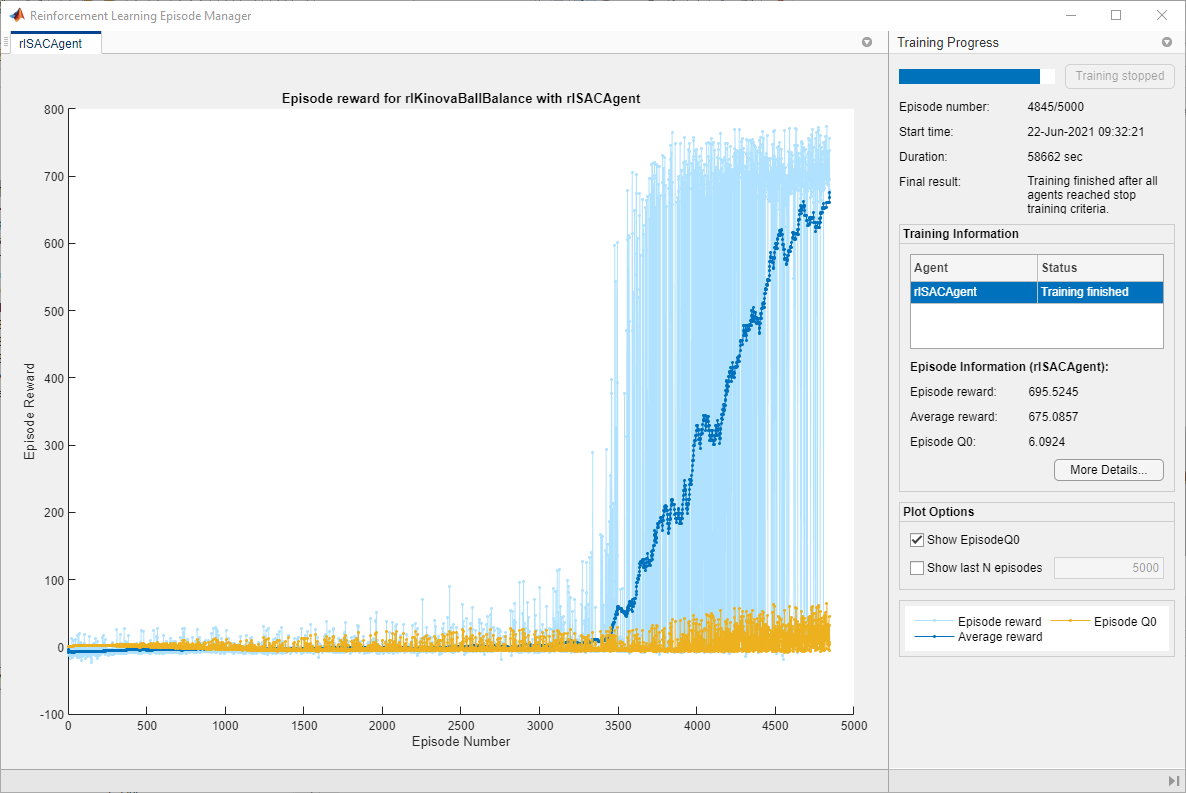

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    agentName = ['BBC-SAC-revised-2-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(rewardWeights(1))+...
        "-"+string(rewardWeights(2))+...
        "-"+string(rewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agent, ...
                 'rewardWeights', rewardWeights, ...
                 'agentOptions', agentOpts, ...
                 'criticNetwork', criticdlnet, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/DRL_training/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

BBC-SAC-revised-2-23-Jul-0.2-2-0.1 saved


## Simulate Trained Agent

To validate the trained agent, run the Simulink model.

Define an arbitrary initial position for the ball with respect to the plate center. To view the agent performance in different situations, change this to other locations on the plate.

% ball.x0 = 0.10;
% ball.y0 = -0.10;
% in = Simulink.SimulationInput(mdl);
% in = setVariable(in,"ball",ball);

% isTerminate = false;
maxsteps = Tf/Ts;
simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
[ball,R6_q0,R7_q0,U0] = BBC_ResetFun();
experiences = sim(env,agent,simOpts);
 
% state
x_ball = experiences.SimulationInfo.logsout.getElement('x_ball').Values.Data;
y_ball =  experiences.SimulationInfo.logsout.getElement('y_ball').Values.Data;
plate_yaw =  experiences.SimulationInfo.logsout.getElement('plate_yaw').Values.Data;
plate_pitch =  experiences.SimulationInfo.logsout.getElement('plate_pitch').Values.Data;
plate_roll =  experiences.SimulationInfo.logsout.getElement('plate_roll').Values.Data;
theta_J6 =  experiences.SimulationInfo.logsout.getElement('theta_J6').Values.Data;
theta_J7 =  experiences.SimulationInfo.logsout.getElement('theta_J7').Values.Data;
is_outside =  experiences.SimulationInfo.logsout.getElement('is_outside').Values.Data;
% action
torque_J6 =  experiences.SimulationInfo.logsout.getElement('torque_J6').Values.Data;
torque_J7 =  experiences.SimulationInfo.logsout.getElement('torque_J7').Values.Data;
% reward
plate_reward =  experiences.SimulationInfo.logsout.getElement('plate_reward').Values.Data;
ball_reward =  experiences.SimulationInfo.logsout.getElement('ball_reward').Values.Data;
stable_reward =  experiences.SimulationInfo.logsout.getElement('stable_reward').Values.Data;
final_reward =  experiences.SimulationInfo.logsout.getElement('final_reward').Values.Data;

steps = length(x_ball);
time = 0:Ts_sample:(steps-1)*Ts_sample;

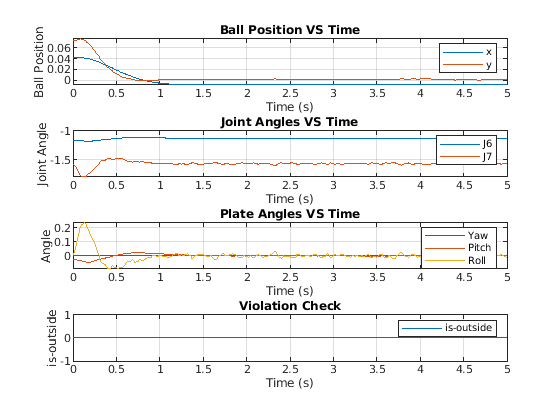


% plotting
figure(1);
subplot(4,1,1)
plot(time,x_ball, time,y_ball);
title('Ball Position VS Time');
legend('x', 'y');
xlabel('Time (s)');
ylabel('Ball Position');
grid on;

subplot(4,1,2)
plot(time,theta_J6, time,theta_J7);
title('Joint Angles VS Time');
legend('J6', 'J7');
xlabel('Time (s)');
ylabel('Joint Angle');
grid on;

subplot(4,1,3)
plot(time,plate_yaw, time,plate_pitch, time,plate_roll);
title('Plate Angles VS Time');
legend('Yaw', 'Pitch', 'Roll');
xlabel('Time (s)');
ylabel('Angle');
grid on;

subplot(4,1,4)
plot(time,is_outside);
title('Violation Check');
legend('is-outside');
xlabel('Time (s)');
ylabel('is-outside');
grid on;

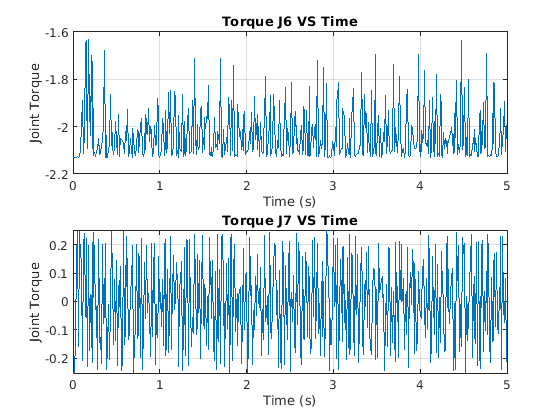


figure(2);
subplot(2,1,1)
plot(time,torque_J6);
title('Torque J6 VS Time');
xlabel('Time (s)');
ylabel('Joint Torque');
grid on;

subplot(2,1,2)
plot( time,torque_J7);
title('Torque J7 VS Time');
xlabel('Time (s)');
ylabel('Joint Torque');
grid on;

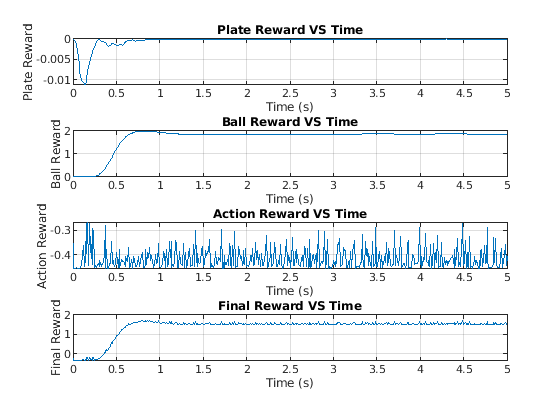


figure(3);
subplot(4,1,1)
plot(time,plate_reward);
title('Plate Reward VS Time');
xlabel('Time (s)');
ylabel('Plate Reward');
grid on;

subplot(4,1,2)
plot(time,ball_reward);
title('Ball Reward VS Time');
xlabel('Time (s)');
ylabel('Ball Reward');
grid on;

subplot(4,1,3)
plot(time,stable_reward);
title('Action Reward VS Time');
xlabel('Time (s)');
ylabel('Action Reward');
grid on;

subplot(4,1,4)
plot(time,final_reward);
title('Final Reward VS Time');
xlabel('Time (s)');
ylabel('Final Reward');
grid on;

## Training progress info

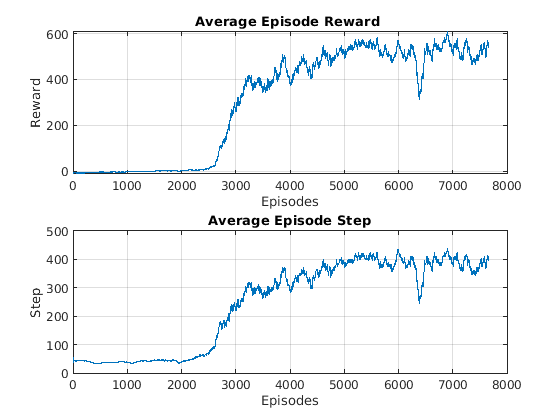

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(4);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on

## Environment Reset Function

function in = kinovaResetFcn(in)
    % Ball parameters
    ball.radius = 0.02;     % m
    ball.mass   = 0.0027;   % kg
    ball.shell  = 0.0002;   % m
    
    % Calculate ball moment of inertia.
    ball.moi = calcMOI(ball.radius,ball.shell,ball.mass);
    
    % Initial conditions. +z is vertically upward.
    % Randomize the x and y distances within the plate.
    ball.x0  = -0.125 + 0.25*rand;  % m, initial x distance from plate center
    ball.y0  = -0.125 + 0.25*rand;  % m, initial y distance from plate center
    ball.z0  = ball.radius;         % m, initial z height from plate surface
    
    ball.dx0 = 0;   % m/s, ball initial x velocity
    ball.dy0 = 0;   % m/s, ball initial y velocity
    ball.dz0 = 0;   % m/s, ball initial z velocity
    
    % Contact friction parameters
    ball.staticfriction     = 0.5;
    ball.dynamicfriction    = 0.3; 
    ball.criticalvelocity   = 1e-3;
    
    % Convert coefficient of restitution to spring-damper parameters.
    coeff_restitution = 0.89;
    [k, c, w] = cor2SpringDamperParams(coeff_restitution,ball.mass);
    ball.stiffness = k;
    ball.damping = c;
    ball.transitionwidth = w;
    
    in = setVariable(in,"ball",ball);
    
    % Randomize joint angles within a range of +/- 5 deg from the 
    % starting positions of the joints.
    R6_q0 = deg2rad(-65) + deg2rad(-5+10*rand);
    R7_q0 = deg2rad(-90) + deg2rad(-5+10*rand);
    in = setVariable(in,"R6_q0",R6_q0);
    in = setVariable(in,"R7_q0",R7_q0);
    
    % Compute approximate initial joint torques that hold the ball,
    % plate and arm at their initial congifuration
    g = 9.80665;
    wrist_torque_0 = ...
        (-1.882 + ball.x0 * ball.mass * g) * cos(deg2rad(-65) - R6_q0);
    hand_torque_0 = ...
        (0.0002349 - ball.y0 * ball.mass * g) * cos(deg2rad(-90) - R7_q0);
    U0 = [wrist_torque_0 hand_torque_0];
    in = setVariable(in,"U0",U0);

    % Animation
%     in = setPostSimFcn(in, @animatedPath);
end